clear, clc, close all
load xm1
load TFp

xPos= xPos(:, 1:960);

xReal= xPos/scaleFactor;
time= [1:length(xReal)]/240;
xGround= xReal(5, :)- xReal(5, 1);

xTFvwd= lsim(TFvwd, xGround, time)+xGround';

xTFn= lsim(TFn, xGround, time)+xGround';

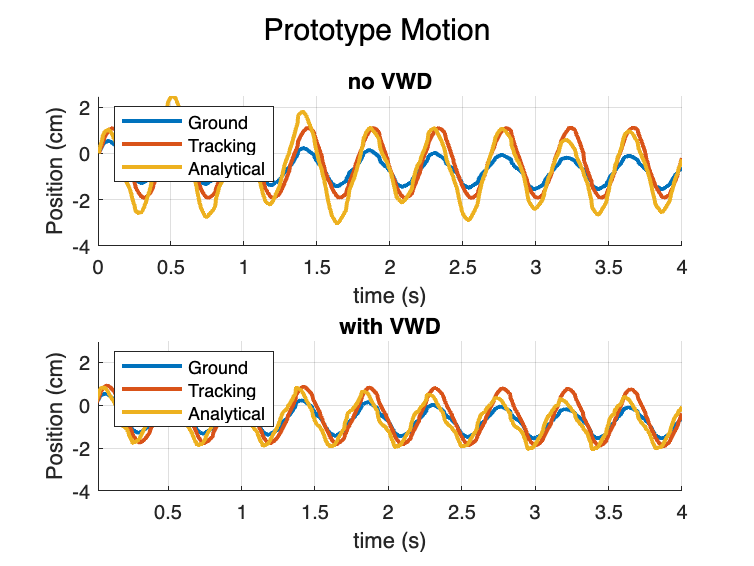


figure(), sgtitle("Prototype Motion")
subplot(2, 1, 1), hold on
plot(time, xGround, DisplayName= "Ground", LineWidth= 2)
plot(time, xReal(4, :)-xReal(4, 1), DisplayName= "Tracking", LineWidth= 2)
plot(time, xTFn, DisplayName= "Analytical", LineWidth= 2)
xlabel("time (s)"), ylabel("Position (cm)"), grid
title("no VWD"), legend(Location= "northwest"), a= axis;

subplot(2, 1, 2), hold on
plot(time, xGround, DisplayName= "Ground", LineWidth= 2)
plot(time, xReal(1, :)-xReal(1, 1), DisplayName= "Tracking", LineWidth= 2)
plot(time, xTFvwd, DisplayName= "Analytical", LineWidth= 2)
xlabel("time (s)"), ylabel("Position (cm)"), grid
title("with VWD"), legend(Location= "northwest"), axis(a)

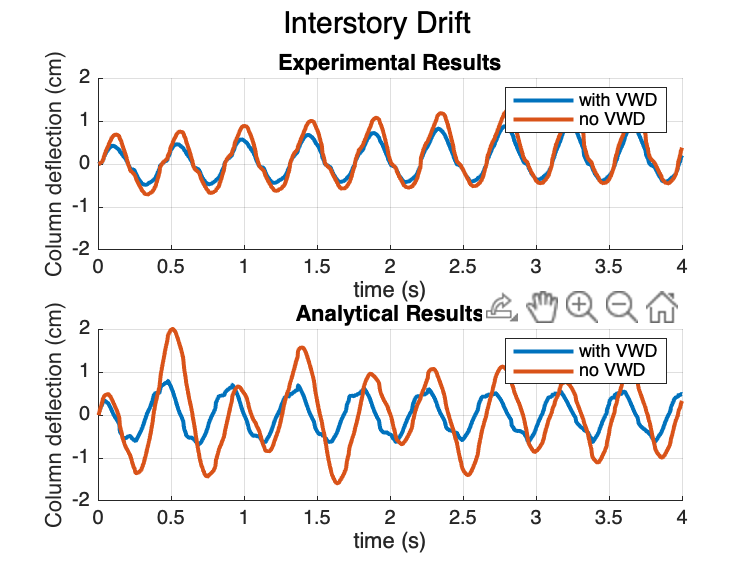


figure(), sgtitle("Interstory Drift")
subplot(2, 1, 2), hold on
plot(time, xTFvwd-xGround', DisplayName= "with VWD", LineWidth= 2)
plot(time, xTFn-xGround', DisplayName= "no VWD", LineWidth= 2)
xlabel("time (s)"), ylabel("Column deflection (cm)"), grid
title("Analytical Results"), a= axis; legend

subplot(2, 1, 1), hold on
plot(time, [xReal(1, :)-xReal(1, 1)]-xGround, DisplayName= "with VWD", LineWidth= 2)
plot(time, [xReal(4, :)-xReal(4, 1)]-xGround, DisplayName= "no VWD", LineWidth= 2)
xlabel("time (s)"), ylabel("Column deflection (cm)"), grid
title("Experimental Results"), axis(a), legend

% AN
%[nMax, nMin]= localMaxMin(xTFn-xGround')
%[dMax, dMin]= localMaxMin(xTFvwd-xGround')

% EXP
[nMax, nMin]= localMaxMin([xReal(4, :)-xReal(4, 1)]-xGround)

nMax = 1×9 single row vector
    0.6856    0.7613    0.8886    1.0070    1.0814    1.1882    1.2555    1.3306    1.3161


nMin = 1×9 single row vector
   -0.1882   -0.1577   -0.4140   -0.0292   -0.0319   -0.4895   -0.4350   -0.4233   -0.4032


[dMax, dMin]= localMaxMin([xReal(1, :)-xReal(1, 1)]-xGround)

dMax = 1×9 single row vector
    0.4232    0.0203    0.5725    0.6795    0.7246    0.8260    0.8813    0.9667    0.8758


dMin = 1×9 single row vector
   -0.1184   -0.0898   -0.0681   -0.0261   -0.0443   -0.0143   -0.3566   -0.0118   -0.4138



nM= mean(nMax(1:6) - nMin(1:6)) % first 6 peaks

nM = single
1.1537

dM= mean(dMax(1:6) - dMin(1:6)) % first 6 peaks

dM = single
0.6012

100*abs((nM-dM)/nM)

ans = single
47.8954